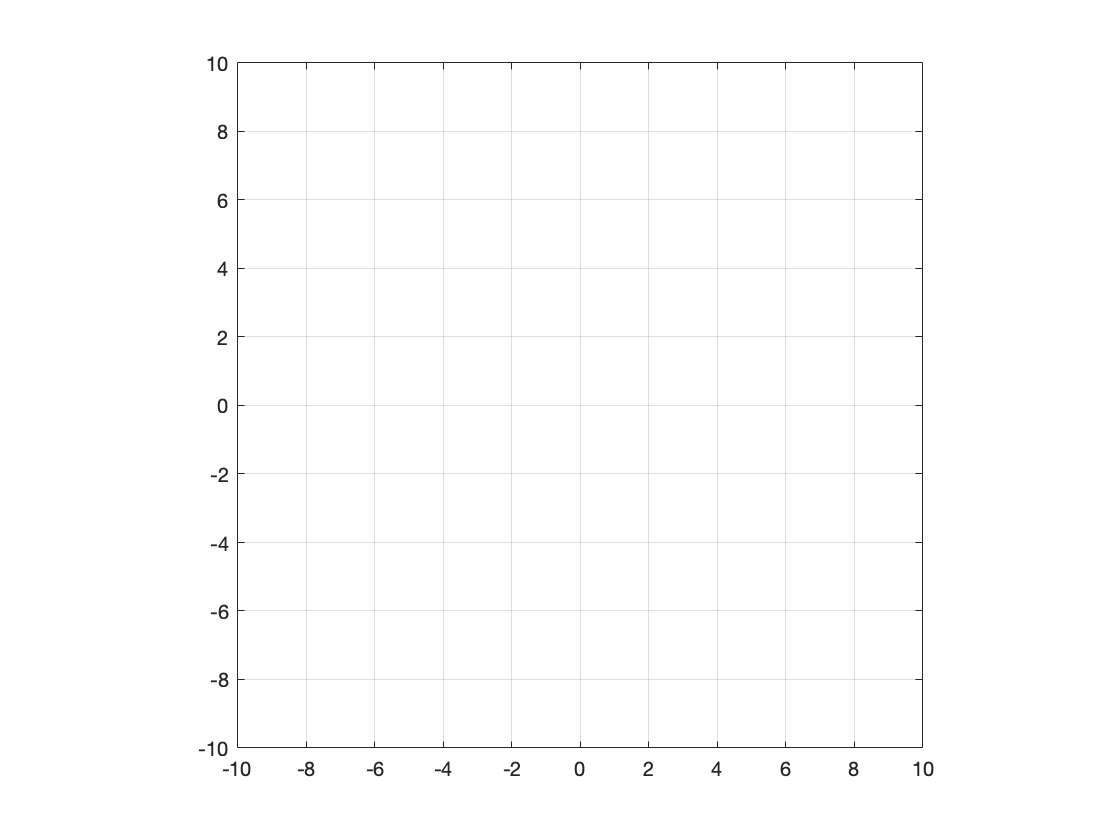

t = -pi:pi;
b1 =4;
b2 =-3;
m1 =0;
% m2 =-4;
m2 = m1*b2/b1;
xt = b1+m1*t;
yt = b2+m2*t;
plot(xt,yt), axis equal, grid on
xlim([-10 10])
ylim([-10 10])

syms m1 b1 m2 b2 t xp yp dsquared
assume([m1 b1 m2 b2 t xp yp dsquared], 'real')
X = [xp; yp];
xt = m1*t + b1;
yt = m2*t + b2;
dsquared = (xt - xp)^2 + (yt - yp)^2

$$dsquared = {\left(b_{1}-\mathrm{xp}+m_{1}\,t\right)}^{2}+{\left(b_{2}-\mathrm{yp}+m_{2}\,t\right)}^{2}$$

% e = (xt - xp) + (yt - yp)
dsquareddot = diff(dsquared,t)

$$dsquareddot = 2\,m_{1}\,\left(b_{1}-\mathrm{xp}+m_{1}\,t\right)+2\,m_{2}\,\left(b_{2}-\mathrm{yp}+m_{2}\,t\right)$$

assume(dsquareddot,'real')
t0 = solve(dsquareddot == 0, t, 'Real',true)

$$t0 = -\frac{2\,m_{1}\,\left(b_{1}-\mathrm{xp}\right)+2\,m_{2}\,\left(b_{2}-\mathrm{yp}\right)}{2\,{m_{1}}^{2}+2\,{m_{2}}^{2}}$$

t0 = simplify(t0,'Steps',100)

$$t0 = -\frac{m_{1}\,\left(b_{1}-\mathrm{xp}\right)+m_{2}\,\left(b_{2}-\mathrm{yp}\right)}{{m_{1}}^{2}+{m_{2}}^{2}}$$


dsquaredmin = subs(dsquared,t,t0)

$$dsquaredmin = {\left(\mathrm{xp}-b_{1}+\frac{m_{1}\,\left(m_{1}\,\left(b_{1}-\mathrm{xp}\right)+m_{2}\,\left(b_{2}-\mathrm{yp}\right)\right)}{{m_{1}}^{2}+{m_{2}}^{2}}\right)}^{2}+{\left(\mathrm{yp}-b_{2}+\frac{m_{2}\,\left(m_{1}\,\left(b_{1}-\mathrm{xp}\right)+m_{2}\,\left(b_{2}-\mathrm{yp}\right)\right)}{{m_{1}}^{2}+{m_{2}}^{2}}\right)}^{2}$$

dsquaredmin = simplify(dsquaredmin,'Steps',100)

$$dsquaredmin = \frac{{\left(b_{1}\,m_{2}-b_{2}\,m_{1}-m_{2}\,\mathrm{xp}+m_{1}\,\mathrm{yp}\right)}^{2}}{{m_{1}}^{2}+{m_{2}}^{2}}$$


A = jacobian(dsquaredmin,X);
A = simplify(A,'Steps',100)

$$A = \left(\begin{array}{cc} -\frac{2\,m_{2}\,\left(b_{1}\,m_{2}-m_{2}\,\mathrm{xp}\right)-2\,m_{1}\,m_{2}\,\left(b_{2}-\mathrm{yp}\right)}{{m_{1}}^{2}+{m_{2}}^{2}} & -\frac{2\,m_{1}\,\left(b_{2}\,m_{1}-m_{1}\,\mathrm{yp}\right)-2\,m_{1}\,m_{2}\,\left(b_{1}-\mathrm{xp}\right)}{{m_{1}}^{2}+{m_{2}}^{2}} \end{array}\right)$$

b1 = 1;
b2 = 2;
m1 = 3;
m2 = -4;
e1 = subs(dsquaredmin)

$$e1 = 0.0400\,{\left(4\,\mathrm{xp}+3\,\mathrm{yp}-10\right)}^{2}$$

dis = simplify(sqrt(e1),'Steps',100)

$$dis = 0.2000\,\sqrt{{\left(4\,\mathrm{xp}+3\,\mathrm{yp}-10\right)}^{2}}$$

f = matlabFunction(dis,'Vars',[xp yp])

f = function_handle with value:
    @(xp,yp)sqrt((xp.*4.0+yp.*3.0-1.0e+1).^2)./5.0


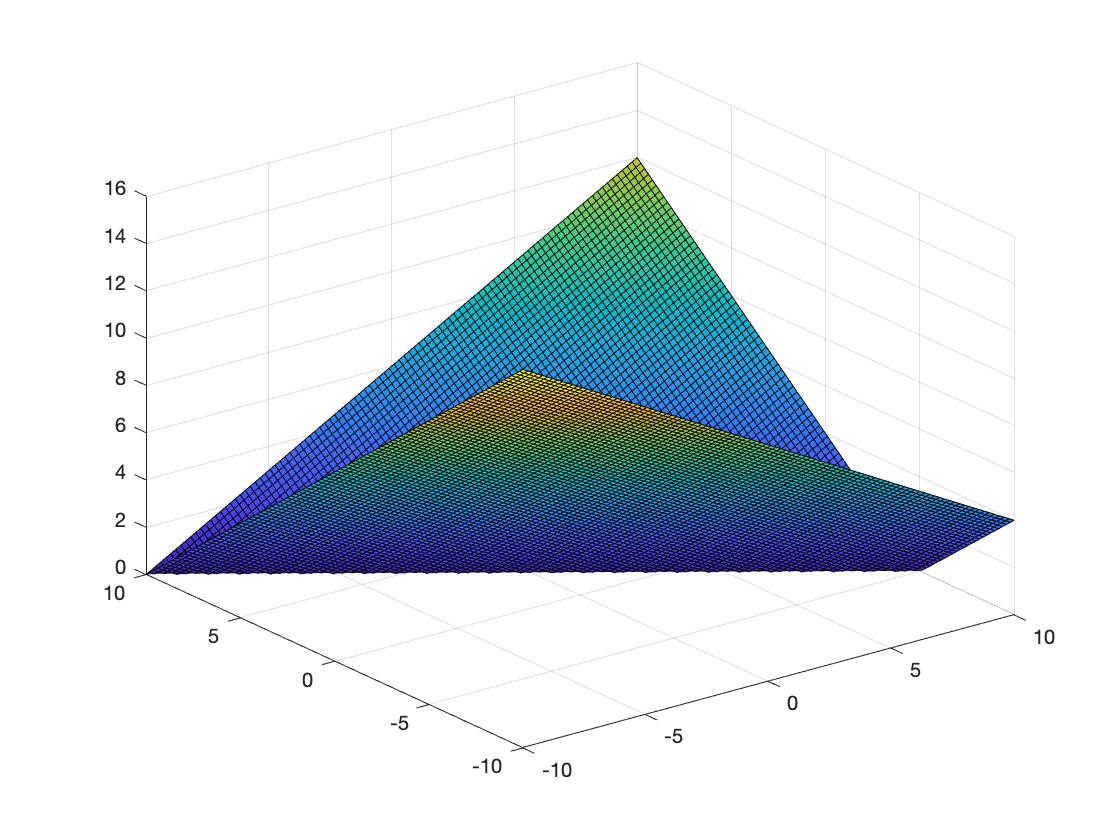

dism = zeros(100,100);
xps = linspace(-10,10,100);
yps = linspace(-10,10,100);
for xi = 1:100
    for yi = 1:100
        dism(xi,yi) = f(xps(xi), yps(yi));
    end
end
surf(xps,yps,dism)